Load transfer ratio: steer

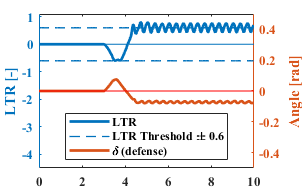


f = figure;
f.Units = 'centimeters';
f.Position = [10 10 8 5];

hold on;
yyaxis left
% l1 = plot(Time, ltr_e,'LineWidth', 2, 'DisplayName','LTR(no defense)');
ylabel('LTR [-]')

% Abnormal message
yyaxis right
% delta = deg2rad((Steer_R1 + Steer_L1)/2); 
% l2 = plot(Time,delta, 'r','LineWidth', 2, 'DisplayName','\delta (no defense)');
ylabel('Angle [rad]')


% % Defence
yyaxis left
load('..\CarSim outputs\With Cargo\LTR only\LastRunLTRstr80kph0degDef.mat')
% 
ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg
% 
l3 = plot(Time, ltr_e, '-','LineWidth', 2, 'DisplayName','LTR');

%% Threshold
yyaxis left
l4 = plot(Time, ones(length(Time),1)*0.6, '--','LineWidth', 1, 'DisplayName','LTR Threshold \pm 0.6');
l5 =  plot(Time, -ones(length(Time),1)*0.6, '--','LineWidth', 1);

ylim([-4.5 1.1])

% % Abnormal message
yyaxis right
delta = deg2rad((Steer_R1 + Steer_L1)/2); 
l6 = plot(Time,delta, '-','LineWidth', 2, 'DisplayName','\delta (defense)');
% ylabel('Angle [rad]')

ylim([-0.5 0.5])
yticks(-0.4:0.2:0.4)

Xlim = [0 10];
xlim(Xlim)
yyaxis left
l0l = plot(Xlim,[0 0], '-','LineWidth', 0.5);
yyaxis right
l0r = plot(Xlim,[0 0], 'r-','LineWidth', 0.5);

legend([l3 l4 l6 ],'location','south');


set(gca, 'FontName','Times New Roman','FontSize',10, 'FontWeight', 'bold');

box on
exportgraphics(gcf,'LTRsteerWith.pdf','ContentType','vector')

Brake increase

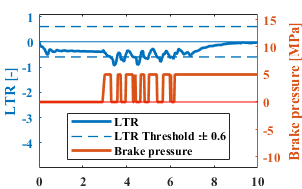

% load('..\CarSim outputs\With Cargo\LTR only\LastRunLTR180kph45deg.mat')

% ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg

f2 = figure;
f2.Units = 'centimeters';
f2.Position = [10 10 8 5];

hold on;
yyaxis left
% l1 = plot(Time, ltr_e,'LineWidth', 2, 'DisplayName','LTR(no defense)');
ylabel('LTR [-]')

% Abnormal message
yyaxis right
% l2 = plot(Time,PbkCh_L1, 'r','LineWidth', 2, 'DisplayName','Brake pressure (no defense)');
ylabel('Angle [rad]')


% Defence
yyaxis left
load('..\CarSim outputs\With Cargo\LTR only\LastRunLTRbrk70kph40degDef.mat')

ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg

l3 = plot(Time, ltr_e, '-','LineWidth', 2, 'DisplayName','LTR');

%% Threshold
l4 = plot(Time, ones(length(Time),1)*0.6, '--','LineWidth', 1, 'DisplayName','LTR Threshold \pm 0.6');
l5 =  plot(Time, -ones(length(Time),1)*0.6, '--','LineWidth', 1);

ylim([-5 1.1])
yticks(-4:1)

% Abnormal message
yyaxis right

l6 = plot(Time,PbkCh_L1, '-','LineWidth', 2, 'DisplayName','Brake pressure');
ylabel('Brake pressure [MPa]')

ylim([-12 16])



Xlim = [0 10];
xlim(Xlim)
yyaxis left
l0l = plot(Xlim,[0 0], '-','LineWidth', 0.5);
yyaxis right
l0r = plot(Xlim,[0 0], 'r-','LineWidth', 0.5);

legend([l3 l4 l6],'location','south');

set(gca, 'FontName','Times New Roman','FontSize',10, 'FontWeight', 'bold');
box on
exportgraphics(gcf,'LTRbrkWith.pdf','ContentType','vector')

Brake reduce

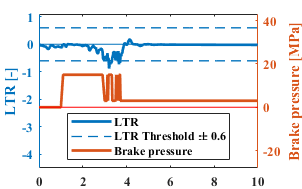


% load('..\CarSim outputs\With Cargo\LTR only\LastRunLTR130kph37deg.mat')

% ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg

f2 = figure;
f2.Units = 'centimeters';
f2.Position = [10 10 8 5];

hold on;
yyaxis left
% l1 = plot(Time, ltr_e,'LineWidth', 2, 'DisplayName','LTR(no defense)');
ylabel('LTR [-]')

% Abnormal message
yyaxis right
% l2 = plot(Time,PbkCh_L1, 'r','LineWidth', 2, 'DisplayName','Brake pressure (no defense)');


% Defence
yyaxis left
load('..\CarSim outputs\With Cargo\LTR only\LastRunLTRreducBrk80kph9degDef.mat')

ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg

l3 = plot(Time, ltr_e, '-','LineWidth', 2, 'DisplayName','LTR');

%% Threshold
l4 = plot(Time, ones(length(Time),1)*0.6, '--','LineWidth', 1, 'DisplayName','LTR Threshold \pm 0.6');
l5 =  plot(Time, -ones(length(Time),1)*0.6, '--','LineWidth', 1);

ylim([-4.5 1.1])

% Abnormal message
yyaxis right

l6 = plot(Time,PbkCh_L1, '-','LineWidth', 2, 'DisplayName','Brake pressure');
ylabel('Brake pressure [MPa]')

ylim([-28 43])

Xlim = [0 10];
xlim(Xlim)
yyaxis left
l0l = plot(Xlim,[0 0], '-','LineWidth', 0.5);
yyaxis right
l0r = plot(Xlim,[0 0], 'r-','LineWidth', 0.5);


legend([l3 l4 l6],'location','south');

set(gca, 'FontName','Times New Roman','FontSize',10, 'FontWeight', 'bold');
box on
exportgraphics(gcf,'LTRreduceBrkWith.pdf','ContentType','vector')

Increase throttle

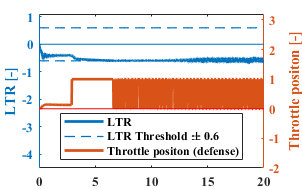

% load('..\CarSim outputs\With Cargo\LTR only\LastRunLTR185kph46deg.mat')

% ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg

f2 = figure;
f2.Units = 'centimeters';
f2.Position = [10 10 8 5];

hold on;
yyaxis left
% l1 = plot(Time, ltr_e,'LineWidth', 2, 'DisplayName','LTR(no defense)');
ylabel('LTR [-]')

% Abnormal message
yyaxis right
% l2 = plot(Time,Throttle, 'r','LineWidth', 2, 'DisplayName','Throttle positon (no defense)');
ylabel('Throttle positon [-]')


% Defence
yyaxis left
load('..\CarSim outputs\With Cargo\LTR only\LastRunLTRacc80kph55degDef.mat')

ltr_e = LTR(Ay*9.81, 9.81, 0.9345, 1.675); % 0.728m -> 250kg  0.9345m -> 600kg

l3 = plot(Time, ltr_e, '-','LineWidth', 2, 'DisplayName','LTR');

%% Threshold
l4 = plot(Time, ones(length(Time),1)*0.6, '--','LineWidth', 1, 'DisplayName','LTR Threshold \pm 0.6');
l5 =  plot(Time, -ones(length(Time),1)*0.6, '--','LineWidth', 1);

ylim([-4.5 1.1])

% Abnormal message
yyaxis right

l6 = plot(Time, Throttle, '-','LineWidth', 2, 'DisplayName','Throttle positon (defense)');
% ylabel('Throttle positon [-]')

ylim([-2 3.2])

Xlim = [0 20];
xlim(Xlim)
yyaxis left
l0l = plot(Xlim,[0 0], '-','LineWidth', 0.5);
yyaxis right
l0r = plot(Xlim,[0 0], 'r-','LineWidth', 0.5);

legend([l3 l4 l6],'location','south');
% xlim([0 4.1])

set(gca, 'FontName','Times New Roman','FontSize',10, 'FontWeight', 'bold');
box on
exportgraphics(gcf,'LTRaccWith.pdf','ContentType','vector')



% exportgraphics(gcf,'roll over brake.pdf','ContentType','vector') %save figure


